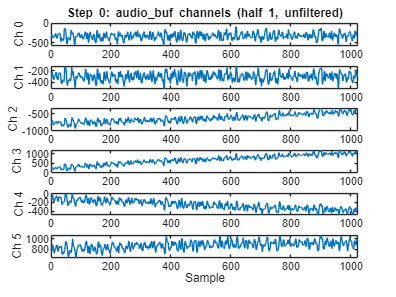

% plot_audio_buf_steps_doa.m
% Parses a raw .bin memory dump of:
%   int16_t audio_buf[2][N_CHANS][SAMPLES_PER_HALF_PER_CHAN]
% exported from STM32CubeIDE, plots each channel, bandpass-filters each
% channel with the same 4th-order (2-stage) biquad cascade running on
% the STM32 (arm_biquad_casd_df1_inst_f32), then walks through GCC-PHAT
% one stage at a time (FFT -> cross-power spectrum -> PHAT weighting ->
% frequency-domain taper -> IFFT -> peak search), plotting the result of
% each stage instead of calling MATLAB's built-in gccphat() as one black
% box.
% Only processes the first half of the double buffer.
%
% Extended from the original: computes GCC-PHAT TDOA for ALL C(6,2)=15
% mic pairs (not just vs. one reference channel), feeds them into the
% geometry least-squares solver, and reports a direction of arrival.
%
% Frequency-domain taper: on top of the time-domain 200-4000 Hz biquad
% bandpass, the PHAT-weighted cross-power spectrum is also tapered to
% zero outside 200-4000 Hz (with a raised-cosine ramp at each edge,
% rather than a hard rectangular cutoff) before the IFFT. This is
% applied AFTER PHAT normalization, not before/on Gxy or X directly -
% PHAT divides by |Gxy|, so any real positive weighting applied before
% that division just gets normalized back out. Applying it after PHAT
% is what actually keeps low-SNR out-of-band bins from contributing
% full-weight noise to the cross-correlation.

clear; clc;

filepath = "C:\Users\Cole\Desktop\mic_array\recordings\recording5_mic12_white\recording5.bin";
% filepath = "C:\Users\Cole\Desktop\mic_array\recordings\recording1_mic4_440hz\recording1.bin";

beta = 0.6;

DTYPE = 'float32';
N_HALVES = 2;
N_CHANS = 6;

SAMPLES = 1024;
% Fs = 53710;
Fs = 15797;
SPEED_OF_SOUND = 343; % m/s
MAX_LAG_S = 0.08/343; % 0.08 m = array diameter (2*RADIUS_M below), upper bound for ANY pair

%% Biquad bandpass filter definition (mirrors STM32 arm_biquad_casd_df1_inst_f32)
% 4th order DF1 SOS bandpass, 200 Hz to 4000 Hz, 2 cascaded stages.
% Columns are [b0 b1 b2 a1 a2] using the CMSIS DF1 sign convention:
%   y[n] = b0*x[n] + b1*x[n-1] + b2*x[n-2] + a1*y[n-1] + a2*y[n-2]
% (note: CMSIS a1/a2 are ADDED, unlike MATLAB's filter()/sos convention
% where they'd be subtracted - do not feed this straight into sosfilt).
biquad_coeffs = [ ...
    0.180596607689788, 0.361193215379576, 0.180596607689788, 0.482059939292023, -0.227137695705591,; ... % Stage 1
    1, -2, 1, 1.94387140037728, -0.945499607031652 ...  % Stage 2
];
N_STAGES = size(biquad_coeffs, 1);

%% Frequency-domain taper definition (applied to Gxy_phat, after PHAT)
% Same 200-4000 Hz passband as the time-domain biquad, but implemented
% as a raised-cosine (Tukey-style) window instead of a hard cutoff, to
% avoid Gibbs ringing / sidelobes in the cross-correlation that a
% rectangular bin-zeroing would introduce.
USE_FREQ_TAPER = false; % true = apply W to Gxy_phat below, false = skip entirely (W left as all-ones, no-op)
F_LO = 200;       % Hz, passband lower edge
F_HI = 4000;      % Hz, passband upper edge
TAPER_HZ = 100;   % Hz, width of the cosine ramp on each edge (only matters if USE_FREQ_TAPER = true; 0 = hard rectangular cutoff instead of a ramp)

%% Step 0: Load raw buffer and plot each channel in the time domain
fid = fopen(filepath, 'r');
if fid == -1
    error('Could not open file: %s', filepath);
end
raw = fread(fid, Inf, [DTYPE '=>double']);
fclose(fid);

expected = N_HALVES * N_CHANS * SAMPLES;
if numel(raw) ~= expected
    error('Expected %d samples, got %d. Check DTYPE/dims or file path.', expected, numel(raw));
end

buf = reshape(raw, [SAMPLES, N_CHANS, N_HALVES]); % buf(sample, chan, half)
buf_raw = squeeze(buf(:,:,1)); % SAMPLES x N_CHANS, half 1 only, unfiltered

%% Optional: swap channels within each SAI interface pair
% Each SAI interface carries 2 of the 6 channels (SAI1 -> ch0/ch1,
% SAI2 -> ch2/ch3, SAI3 -> ch4/ch5). Comment out any line below to
% leave that interface's channel order as-is; uncomment to swap it.
% Columns are 1-indexed here, so ch0/ch1 = columns 1/2, etc.
% buf_raw(:, [1 2]) = buf_raw(:, [2 1]); % swap ch0 <-> ch1 (SAI1)
% buf_raw(:, [3 4]) = buf_raw(:, [4 3]); % swap ch2 <-> ch3 (SAI2)
% buf_raw(:, [5 6]) = buf_raw(:, [6 5]); % swap ch4 <-> ch5 (SAI3)

t = (0:size(buf_raw,1)-1);

figure('Name', 'Step 0: Raw time-domain channels');
for ch = 1:N_CHANS
    subplot(N_CHANS, 1, ch);
    plot(t, buf_raw(:,ch));
    xlim([0 SAMPLES]);
    ylabel(sprintf('Ch %d', ch-1));
    if ch == 1
        title('Step 0: audio\_buf channels (half 1, unfiltered)');
    end
    if ch == N_CHANS
        xlabel('Sample');
    end
end

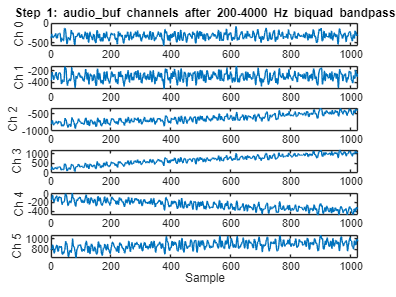


%% Step 1: Bandpass filter each channel (biquad cascade DF1, matches firmware)
biquad_state = zeros(N_STAGES, 4, N_CHANS); % [x1 x2 y1 y2] per stage per chan, zero-init like biquad_state[N_CHANS][4*2]={0}

buf_full = zeros(size(buf_raw)); % filtered signal, feeds all downstream steps
for ch = 1:N_CHANS
    [y_ch, biquad_state(:,:,ch)] = biquadCascadeDF1(buf_raw(:,ch), biquad_coeffs, biquad_state(:,:,ch));
    buf_full(:,ch) = y_ch;
end
buf_full = buf_raw;

figure('Name', 'Step 1: Bandpass-filtered time-domain channels');
for ch = 1:N_CHANS
    subplot(N_CHANS, 1, ch);
    plot(t, buf_full(:,ch));
    xlim([0 SAMPLES]);
    ylabel(sprintf('Ch %d', ch-1));
    if ch == 1
        title('Step 1: audio\_buf channels after 200-4000 Hz biquad bandpass');
    end
    if ch == N_CHANS
        xlabel('Sample');
    end
end

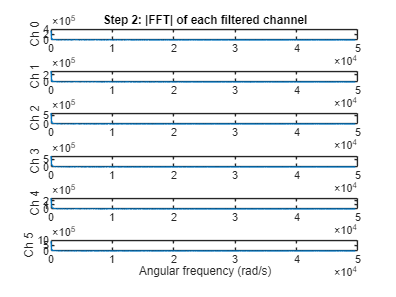


%% Step 2: FFT of every (filtered) channel (shared by all pairs)
NFFT = 2^nextpow2(2*SAMPLES - 1);
freqs = Fs * (0:NFFT-1) / NFFT;
omega = 2*pi*freqs;

X = fft(buf_full, NFFT, 1); % NFFT x N_CHANS

figure('Name', 'Step 2: FFT magnitude of each channel');
for ch = 1:N_CHANS
    subplot(N_CHANS, 1, ch);
    plot(omega(1:NFFT/2), abs(X(1:NFFT/2, ch)));
    ylabel(sprintf('Ch %d', ch-1));
    if ch == 1
        title('Step 2: |FFT| of each filtered channel');
    end
    if ch == N_CHANS
        xlabel('Angular frequency (rad/s)');
    end
end

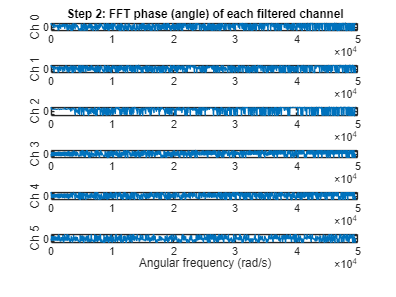


figure('Name', 'Step 2: FFT phase of each channel');
for ch = 1:N_CHANS
    subplot(N_CHANS, 1, ch);
    plot(omega(1:NFFT/2), angle(X(1:NFFT/2, ch)));
    ylabel(sprintf('Ch %d', ch-1));
    ylim([-pi pi]);
    if ch == 1
        title('Step 2: FFT phase (angle) of each filtered channel');
    end
    if ch == N_CHANS
        xlabel('Angular frequency (rad/s)');
    end
end

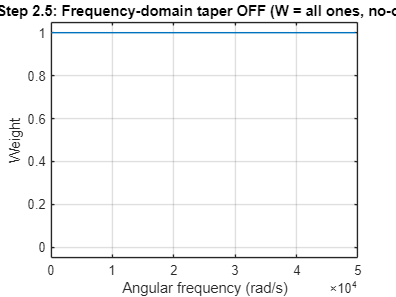


%% Step 2.5: Build the frequency-domain taper window (shared by all pairs)
% freqs(k) is the "positive-index" frequency Fs*(k-1)/NFFT. For bins
% past Nyquist (k > NFFT/2) that value is actually representing a
% negative frequency of freqs(k) - Fs; fold it back to get the true
% |frequency| of that bin so the taper is symmetric, which keeps
% Gxy_phat's Hermitian symmetry intact (so the ifft below stays real).
if USE_FREQ_TAPER
    freq_folded = freqs;
    freq_folded(freq_folded > Fs/2) = Fs - freq_folded(freq_folded > Fs/2);
    W = freqTaper(freq_folded, F_LO, F_HI, TAPER_HZ);
    W = W(:); % NFFT x 1, column to match Gxy_phat
    taper_title = sprintf('Step 2.5: Raised-cosine taper, passband %d-%d Hz, %d Hz ramp', F_LO, F_HI, TAPER_HZ);
else
    W = ones(NFFT, 1); % no-op, Gxy_phat .* W below leaves Gxy_phat unchanged
    taper_title = 'Step 2.5: Frequency-domain taper OFF (W = all ones, no-op)';
end

figure('Name', 'Step 2.5: Frequency-domain taper window');
plot(omega(1:NFFT/2), W(1:NFFT/2));
xlabel('Angular frequency (rad/s)');
ylabel('Weight');
ylim([-0.05 1.05]);
title(taper_title);
grid on;

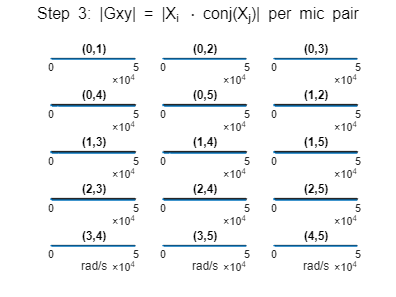


%% Steps 3-5, generalized to every pair (i,j), i<j
% Step 5 produces two figures per pair: 5a shows the full-lag-range
% cross-correlation (so you can see the overall shape / any aliasing or
% secondary peaks), 5b zooms to the physically valid lag window (+/-
% MAX_LAG_S) that the peak search actually operates on.
% Pair order MUST match how A is built in the geometry solver below:
% for i = 1:N_MICS, for j = i+1:N_MICS
lag_samples = (-NFFT/2 : NFFT/2-1)';
lag = lag_samples / Fs;
lag_ms = lag * 1e3;
in_range = abs(lag_ms) <= MAX_LAG_S * 1000;
lag_win = lag(in_range);

pair_list = zeros(0, 2);
tdoa_pairs_s = [];

N_PAIRS = nchoosek(N_CHANS, 2);
GRID_ROWS = 5;
GRID_COLS = 3; % GRID_ROWS*GRID_COLS must be >= N_PAIRS (5x3=15 for 6 chans)

fig_gxy      = figure('Name', 'Step 3: Cross-power spectrum |Gxy| per pair');
fig_gxy_phase = figure('Name', 'Step 3: Cross-power spectrum phase (angle Gxy) per pair');
if USE_FREQ_TAPER
    fig4_name = 'Step 4: PHAT-weighted + tapered cross-power spectrum per pair';
    fig4_sgtitle = 'Step 4: |Gxy| after PHAT-\beta weighting + freq-domain taper per mic pair';
    fig4_phase_name = 'Step 4: PHAT-weighted + tapered cross-power spectrum phase per pair';
    fig4_phase_sgtitle = 'Step 4: angle(Gxy_{phat}) after PHAT-\beta weighting + freq-domain taper per mic pair';
else
    fig4_name = 'Step 4: PHAT-weighted cross-power spectrum per pair (taper off)';
    fig4_sgtitle = 'Step 4: |Gxy| after PHAT-\beta weighting per mic pair (taper off)';
    fig4_phase_name = 'Step 4: PHAT-weighted cross-power spectrum phase per pair (taper off)';
    fig4_phase_sgtitle = 'Step 4: angle(Gxy_{phat}) after PHAT-\beta weighting per mic pair (taper off)';
end
fig_gxy_phat = figure('Name', fig4_name);
fig_gxy_phat_phase = figure('Name', fig4_phase_name);
fig_cc_full  = figure('Name', 'Step 5a: Cross-correlation, full lag range, per pair');
fig_cc_win   = figure('Name', 'Step 5b: Cross-correlation, valid region around 0 lag, per pair');

epsilon = eps;
for i = 1:N_CHANS
    for j = i+1:N_CHANS
        Gxy = X(:, i) .* conj(X(:, j));

        % PHAT-beta weighting
        Gxy_phat = Gxy ./ (abs(Gxy) .^ beta + epsilon);

        % Frequency-domain taper (see USE_FREQ_TAPER above): applied
        % AFTER PHAT normalization. Doing this before PHAT (e.g.
        % tapering Gxy or X directly) would be undone by PHAT's division
        % by |Gxy|, since W is real and positive - it would just cancel
        % out of the magnitude term. When USE_FREQ_TAPER = false, W is
        % all ones and this line is a no-op.
        Gxy_phat = Gxy_phat .* W;

        cc_full = real(ifft(Gxy_phat, NFFT, 1));
        cc = fftshift(cc_full, 1);

        cc_win = cc(in_range);
        [~, idx] = max(cc_win);
        tau_ij = lag_win(idx); % seconds, delay of ch i relative to ch j

        pair_list(end+1, :) = [i, j]; %#ok<AGROW>
        tdoa_pairs_s(end+1, 1) = tau_ij; %#ok<AGROW>

        k = size(pair_list, 1); % running pair index, matches subplot slot
        pair_title = sprintf('(%d,%d)', i-1, j-1);

        figure(fig_gxy);
        subplot(GRID_ROWS, GRID_COLS, k);
        plot(omega(1:NFFT/2), abs(Gxy(1:NFFT/2)));
        title(pair_title);
        if k > (GRID_ROWS-1)*GRID_COLS
            xlabel('rad/s');
        end

        figure(fig_gxy_phase);
        subplot(GRID_ROWS, GRID_COLS, k);
        plot(omega(1:NFFT/2), angle(Gxy(1:NFFT/2)));
        title(pair_title);
        ylim([-pi pi]);
        if k > (GRID_ROWS-1)*GRID_COLS
            xlabel('rad/s');
        end

        figure(fig_gxy_phat);
        subplot(GRID_ROWS, GRID_COLS, k);
        plot(omega(1:NFFT/2), abs(Gxy_phat(1:NFFT/2)));
        title(pair_title);
        if k > (GRID_ROWS-1)*GRID_COLS
            xlabel('rad/s');
        end

        figure(fig_gxy_phat_phase);
        subplot(GRID_ROWS, GRID_COLS, k);
        plot(omega(1:NFFT/2), angle(Gxy_phat(1:NFFT/2)));
        title(pair_title);
        ylim([-pi pi]);
        if k > (GRID_ROWS-1)*GRID_COLS
            xlabel('rad/s');
        end

        figure(fig_cc_full);
        subplot(GRID_ROWS, GRID_COLS, k);
        plot(lag_ms, cc);
        hold on;
        plot(tau_ij*1e3, cc_win(idx), 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 4);
        hold off;
        title(pair_title);
        if k > (GRID_ROWS-1)*GRID_COLS
            xlabel('lag (ms)');
        end

        figure(fig_cc_win);
        subplot(GRID_ROWS, GRID_COLS, k);
        plot(lag_win*1e3, cc_win);
        hold on;
        plot(tau_ij*1e3, cc_win(idx), 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 4);
        hold off;
        title(sprintf('%s: %+.3f ms', pair_title, tau_ij*1e3));
        if k > (GRID_ROWS-1)*GRID_COLS
            xlabel('lag (ms)');
        end
    end
end

sgtitle(fig_gxy, 'Step 3: |Gxy| = |X_i \cdot conj(X_j)| per mic pair');

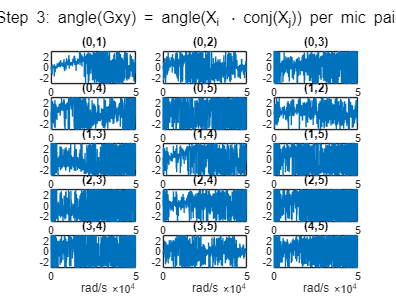

sgtitle(fig_gxy_phase, 'Step 3: angle(Gxy) = angle(X_i \cdot conj(X_j)) per mic pair');

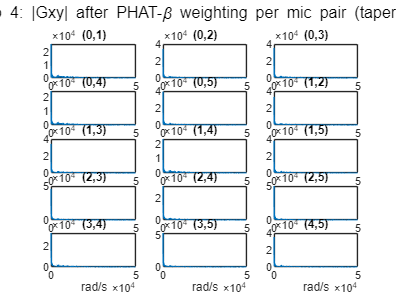

sgtitle(fig_gxy_phat, fig4_sgtitle);

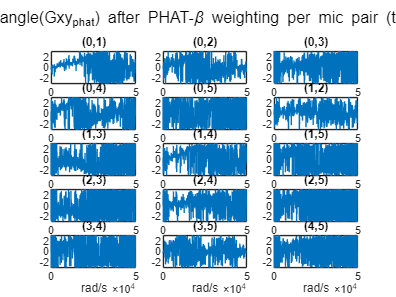

sgtitle(fig_gxy_phat_phase, fig4_phase_sgtitle);

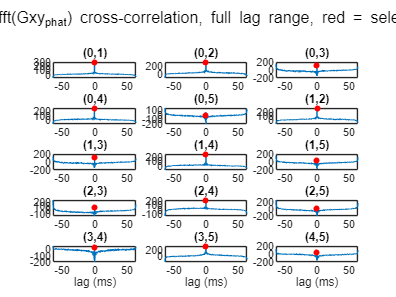

sgtitle(fig_cc_full, 'Step 5a: ifft(Gxy_{phat}) cross-correlation, full lag range, red = selected peak');

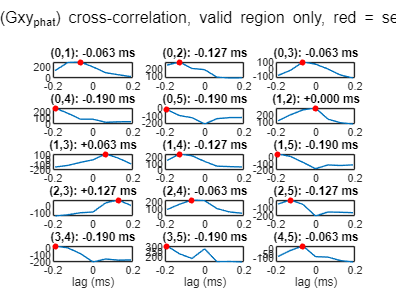

sgtitle(fig_cc_win, 'Step 5b: ifft(Gxy_{phat}) cross-correlation, valid region only, red = selected peak');

% Note: Step 4's phase plot will look almost identical to Step 3's. PHAT
% only rescales |Gxy| to 1 (or W's value, if tapering) - it doesn't touch
% angle(Gxy) at all, since dividing a complex number by a positive real
% scalar leaves its phase unchanged. The only place they can differ is
% where the taper (if on) has driven |Gxy_phat| to ~0 at the band edges,
% where angle() becomes numerically meaningless noise rather than a
% real phase measurement.

fprintf('\nPairwise GCC-PHAT TDOA (i relative to j):\n');


Pairwise GCC-PHAT TDOA (i relative to j):


for k = 1:size(pair_list, 1)
    fprintf('  (%d,%d): %+.3f samples (%+.3f ms)\n', ...
        pair_list(k,1)-1, pair_list(k,2)-1, tdoa_pairs_s(k)*Fs, tdoa_pairs_s(k)*1e3);
end

  (0,1): -1.000 samples (-0.063 ms)
  (0,2): -2.000 samples (-0.127 ms)
  (0,3): -1.000 samples (-0.063 ms)
  (0,4): -3.000 samples (-0.190 ms)
  (0,5): -3.000 samples (-0.190 ms)
  (1,2): +0.000 samples (+0.000 ms)
  (1,3): +1.000 samples (+0.063 ms)
  (1,4): -2.000 samples (-0.127 ms)
  (1,5): -3.000 samples (-0.190 ms)
  (2,3): +2.000 samples (+0.127 ms)
  (2,4): -1.000 samples (-0.063 ms)
  (2,5): -2.000 samples (-0.127 ms)
  (3,4): -3.000 samples (-0.190 ms)
  (3,5): -3.000 samples (-0.190 ms)
  (4,5): -1.000 samples (-0.063 ms)



%% Geometry solver
N_MICS = 6;
RADIUS_CM = 4;
RADIUS_M = RADIUS_CM / 100;

positions = [];
for i = 1:N_MICS
    theta_deg = (i-1) * 360/N_MICS;
    positions = [positions; RADIUS_M*cosd(theta_deg) RADIUS_M*sind(theta_deg)]; % FIX: cosd/sind, not cos/sin
end

A = [];
for i = 1:N_MICS
    for j = i+1:N_MICS
        A = [A; positions(i, :) - positions(j, :)];
    end
end

M = pinv(A' * A) * A'; % left pseudoinverse of A (2 x 15)

%% Step 6: Solve for direction of arrival
% Far-field plane-wave model: arrival time at mic position p is
%   t(p) = t0 - (p . u) / c
% where u is the unit vector pointing FROM the array TOWARD the source.
% So for TDOA tau_ij = t_i - t_j = -(p_i - p_j).u / c = -(A_row_ij . u)/c,
% i.e. b = -(1/c) * A * u  =>  u = -c * pinv(A) * b = -c * M * b
b = tdoa_pairs_s; % 15 x 1, same order as A's rows

u = -SPEED_OF_SOUND * (M * b); % 2 x 1, not yet unit norm
u_norm = norm(u);
u_hat = u / u_norm;

doa_deg = atan2d(u_hat(2), u_hat(1)); % 0 deg = +x axis (mic 1's direction), CCW positive

fprintf('\nEstimated direction of arrival: %.1f deg (0 deg = mic 1 direction, CCW+)\n', doa_deg);


Estimated direction of arrival: 84.0 deg (0 deg = mic 1 direction, CCW+)


fprintf('Solved unit vector magnitude before normalization: %.3f (closer to 1 = more self-consistent fit)\n', u_norm);

Solved unit vector magnitude before normalization: 0.578 (closer to 1 = more self-consistent fit)


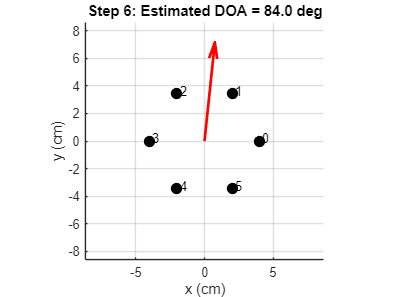


%% Plot array geometry + estimated DOA
figure('Name', 'Step 6: Mic array geometry and estimated DOA');
hold on;
plot(positions(:,1)*100, positions(:,2)*100, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 8);
for i = 1:N_MICS
    text(positions(i,1)*100 + 0.2, positions(i,2)*100 + 0.2, sprintf('%d', i-1));
end
arrow_len = RADIUS_CM * 1.8;
quiver(0, 0, u_hat(1)*arrow_len, u_hat(2)*arrow_len, 0, 'r', 'LineWidth', 2, 'MaxHeadSize', 0.5);
axis equal;
xlim([-arrow_len arrow_len]*1.2);
ylim([-arrow_len arrow_len]*1.2);
xlabel('x (cm)');
ylabel('y (cm)');
title(sprintf('Step 6: Estimated DOA = %.1f deg', doa_deg));
grid on;
hold off;


%% Local functions
function [y, state_out] = biquadCascadeDF1(x, coeffs, state_in)
% Mirrors CMSIS arm_biquad_cascade_df1_f32, run per-channel, per-buffer.
%   coeffs   : nStages x 5 = [b0 b1 b2 a1 a2], CMSIS DF1 sign convention
%              (y[n] = b0*x[n]+b1*x[n-1]+b2*x[n-2] + a1*y[n-1]+a2*y[n-2])
%   state_in : nStages x 4 = [x1 x2 y1 y2] per stage, i.e. the same
%              layout as float32_t biquad_state[N_CHANS][4*nStages]
%              would hold for one channel, zero-initialized like the
%              firmware's biquad_state = {0}.
% Stages are cascaded: stage s's output feeds stage s+1's input, exactly
% as arm_biquad_casd_df1_inst_f32 with numStages = size(coeffs,1) does.
nStages = size(coeffs, 1);
stage_in = x(:);
state_out = state_in;
for s = 1:nStages
    b0 = coeffs(s,1); b1 = coeffs(s,2); b2 = coeffs(s,3);
    a1 = coeffs(s,4); a2 = coeffs(s,5);
    x1 = state_in(s,1); x2 = state_in(s,2);
    y1 = state_in(s,3); y2 = state_in(s,4);
    y = zeros(size(stage_in));
    for n = 1:numel(stage_in)
        xn = stage_in(n);
        yn = b0*xn + b1*x1 + b2*x2 + a1*y1 + a2*y2;
        x2 = x1; x1 = xn;
        y2 = y1; y1 = yn;
        y(n) = yn;
    end
    state_out(s,:) = [x1 x2 y1 y2];
    stage_in = y;
end
end

function w = freqTaper(f, f_lo, f_hi, taper_hz)
% Raised-cosine (Tukey-style) bandpass window over an arbitrary vector
% of (non-negative, already-folded) frequencies f, in Hz.
%   0                                          for f < f_lo - taper_hz
%   0.5*(1 - cos(pi*(f-(f_lo-taper_hz))/taper_hz))  rising ramp
%   1                                          for f_lo <= f <= f_hi
%   0.5*(1 + cos(pi*(f-f_hi)/taper_hz))         falling ramp
%   0                                          for f > f_hi + taper_hz
% taper_hz = 0 degenerates to a hard rectangular cutoff.
w = zeros(size(f));

if taper_hz <= 0
    w(f >= f_lo & f <= f_hi) = 1;
    return;
end

rise_lo = f_lo - taper_hz;
fall_hi = f_hi + taper_hz;

passband = (f >= f_lo) & (f <= f_hi);
w(passband) = 1;

rising = (f >= rise_lo) & (f < f_lo);
w(rising) = 0.5 * (1 - cos(pi * (f(rising) - rise_lo) / taper_hz));

falling = (f > f_hi) & (f <= fall_hi);
w(falling) = 0.5 * (1 + cos(pi * (f(falling) - f_hi) / taper_hz));
end